### Assignment 3: Lens Antenna

The antenna is operating at $f=200\;\mathrm{GHz}$. 

## 1. The far field of the planar antenna in fused silica.

The following constants were given:


$$\epsilon_{r\;} =4,u_0 =v_0 =0\ldotp 5\ldotp$$


Additionally, we consider $r=1$.

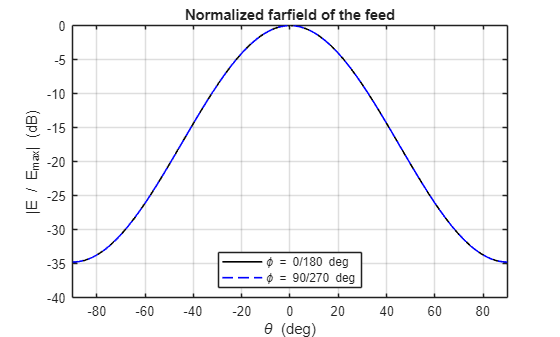

clc; clear; close all;
f = 200e9;
er = 4;
u0 = 0.5;
v0 = 0.5;
r = 1;

lambda_0 = 3e8 / f;
eta_0 = 120 * pi;
eta_d = eta_0 / sqrt(er);

theta = linspace(eps, pi/2, 181);
phi = linspace(eps, 2*pi, 181);
[TH, PH] = meshgrid(theta, phi);

[Eth_feed, Eph_feed, Prad_feed] = FeedLens(f, er, r, TH, PH, u0, v0);

U = sin(TH) .* cos(PH);
V = sin(TH) .* sin(PH);
Eabs = sqrt(abs(Eth_feed).^2 + abs(Eph_feed).^2);
Eabs_dB = 20 * log10(abs(Eabs));
Eabs_dB_norm = Eabs_dB - max(Eabs_dB(:));
Eabs_dB_norm = max(Eabs_dB_norm, -40);

phi_deg = rad2deg(phi);
theta_deg = rad2deg(theta);

%locate the indexes for phi = 0, 90, 180, 270 degrees
[~, idx_phi_0] = min(abs(phi_deg - 0));
[~, idx_phi_90] = min(abs(phi_deg - 90));
[~, idx_phi_180] = min(abs(phi_deg - 180));
[~, idx_phi_270] = min(abs(phi_deg - 270));

cut_phi_0 = Eabs_dB_norm(idx_phi_0, :);
cut_phi_90 = Eabs_dB_norm(idx_phi_90, :);
cut_phi_180 = Eabs_dB_norm(idx_phi_180, :);
cut_phi_270 = Eabs_dB_norm(idx_phi_270, :);

theta_plot = [-fliplr(theta_deg), theta_deg];
cut_phi0_phi180 = [fliplr(cut_phi_180), cut_phi_0];
cut_phi90_phi270 = [fliplr(cut_phi_270), cut_phi_90];

cut_phi0_phi180 = max(cut_phi0_phi180, -40);
cut_phi90_phi270 = max(cut_phi90_phi270, -40);

figure;
plot(theta_plot, cut_phi0_phi180, 'k-', 'LineWidth', 1.2);
hold on; grid on;
plot(theta_plot, cut_phi90_phi270, 'b--', 'LineWidth', 1.2);
xlabel('\theta (deg)');
ylabel('|E / E_{max}| (dB)');
title('Normalized farfield of the feed');
legend('\phi = 0/180 deg', '\phi = 90/270 deg', 'Location', 'south');
xlim([-90 90]);
ylim([-40 0]);

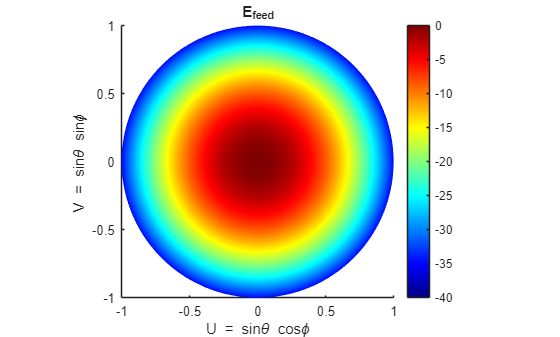


figure;
surface(U, V, Eabs_dB_norm, 'LineStyle', 'none');
axis equal;
axis([-1 1 -1 1]);
xlabel('U = sin\theta cos\phi');
ylabel('V = sin\theta sin\phi');
title('E_{feed}');
colormap(jet);
colorbar;
clim([-40 0]);
view(2);


fprintf('Radiated power inside the lens: %.6g W (for unit field scaling)\n', Prad_feed);

Radiated power inside the lens: 0.00113283 W (for unit field scaling)


The far field can be divided into three components: Amplitude taper, ploarization, and spherical spreading. The sphercial spreading and ploarization components turn into constants when we calculate the magnitude of the far field in dB. Therefore, the antenna in far field should have a shape similar to its amplitude taper. The amplitude taper can be written as:

$e^{-\left\lbrace {\left\lbrack \frac{u}{u_0 }\right\rbrack }^{2\;} +{\left\lbrack \frac{v}{v_0 }\right\rbrack }^2 \right\rbrace }$,

where $u=\sin \theta \;\cos \phi ,v=\sin \theta \;\sin \phi \ldotp$

It can be observed that when $\phi$ is fiixed, the farfield should have the largest amplitude at $\theta =0\;\deg$ and this is indeed what we can oberve in the plotted figures. 

## 2. Fresnel transmission coefficients for a flat fused silica-air interface. 

For a flat fused silica-air interface, the transmitted power ratio can be calculated via the following formula:

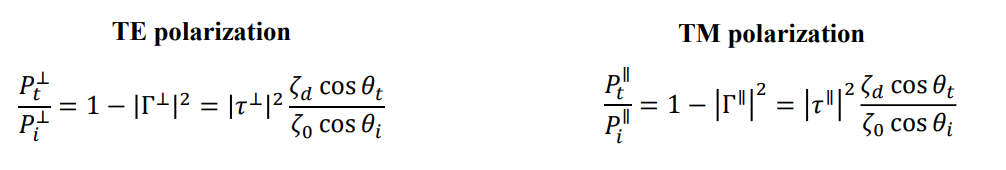

where

, .

The plots for power transmitted over the power incident as a function of the incident plane wave angle for both TE and TM polarized cases can be found below:

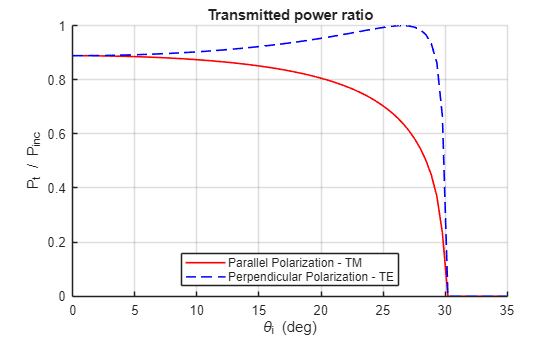

%% Plot transmitted power with respect to the incident power
theta_i = linspace(eps, deg2rad(80), 181);
theta_i_deg = rad2deg(theta_i);

[tau_prp, tau_par, th_t] = Fresnel_Tx_coeff(theta_i, er);

figure;hold on; grid on;

tx_i_prp_ratio = abs(tau_prp).^2 .* (eta_d * cos(th_t)) ./ (cos(theta_i) * eta_0);
tx_i_par_ratio = abs(tau_par).^2 .* (eta_d * cos(th_t)) ./ (cos(theta_i) * eta_0);

plot(theta_i_deg, real(tx_i_prp_ratio), 'r-', 'LineWidth', 1.2);
plot(theta_i_deg, real(tx_i_par_ratio), 'b--', 'LineWidth', 1.2);
xlabel('\theta_i (deg)');
ylabel('P_t / P_{inc}');
title('Transmitted power ratio');
legend('Parallel Polarization - TM', 'Perpendicular Polarization - TE', 'Location', 'south');
xlim([0 35]);
ylim([0 1]);

From the figure above, it can be observe that the total internal reflection occurs when $\theta >30\;\deg$. For any incident angle which is larger than 30 degrees, no power can transmit from the silicon to air. In the lens antenna desgin, we are trying to make the incidient angle on the local surface of the lens antenna smaller than the total internal refleciton angle so the power can actually be transmitted into the air.

## 3. Fresnel transmission coefficients for an untruncated elliptical fused silica lens

Follow the general steps to define a unique elliptical lens antenna, the follow figure can be obtained:

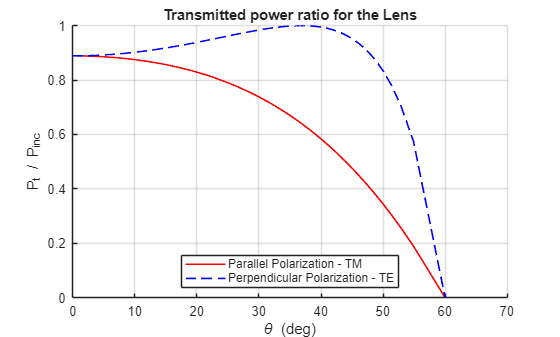

D_l = 9 * lambda_0; % lens diameter
eccentricity = 1 / sqrt(er);
theta_c = asin(eccentricity);
theta_0 = pi/2 - theta_c; % angular domain of the lens

r_min = (D_l / 2) / sin(theta_0);
a = r_min * (1 - eccentricity * cos(theta_0)) / (1 - eccentricity^2);
c = a * eccentricity;
b = sqrt(a^2 - c^2);

rho = linspace(eps, D_l/2, 181);

z = a * sqrt(1 - (rho.^2 ./ b^2)) + c;
th_lens = atan(rho ./ z);

th_i_lens = acos((1 - eccentricity * cos(th_lens)) ./ ...
    sqrt(1 - 2 * eccentricity * cos(th_lens) + eccentricity^2));

[tau_prp_lens, tau_par_lens, th_t_lens] = Fresnel_Tx_coeff(th_i_lens, er);
tx_i_prp_ratio_lens = abs(tau_prp_lens).^2 .* (eta_d * cos(th_t_lens)) ./ (cos(th_i_lens) * eta_0);
tx_i_par_ratio_lens = abs(tau_par_lens).^2 .* (eta_d * cos(th_t_lens)) ./ (cos(th_i_lens) * eta_0);

figure;hold on; grid on;
plot(rad2deg(th_lens(:)), tx_i_prp_ratio_lens(:), 'r-', 'LineWidth', 1.2);
plot(rad2deg(th_lens(:)), tx_i_par_ratio_lens(:), 'b--', 'LineWidth', 1.2);
xlabel('\theta (deg)');
ylabel('P_t / P_{inc}');
title('Transmitted power ratio for the Lens');
legend('Parallel Polarization - TM', 'Perpendicular Polarization - TE', 'Location', 'south');
xlim([0 70]);
ylim([0 1]);

Now we can see the transmitted power ratio with repect to lens angular region $\theta$ intead of angle of incident $\theta_i$ in question 2. The connection between $\theta \;$ and $\theta_{i\;}$ can be found as follows:

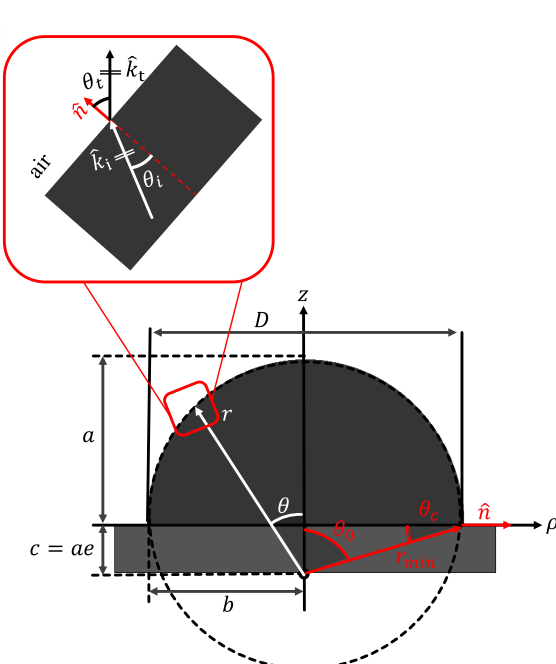

From question 2, we know that we need to keep incident angle smaller than the total internal reflection ($\theta_c$). This can be achieved by setting the angular domian $\theta_0 =90-\theta_c$ considering the worst case angle. This explains the result from the transmitted power ration figure: no power is transmitted after $\theta \;=60\;\deg$ by design. 

## 4.Plot the equivalent aperture current distribution of an elliptical lens antenna

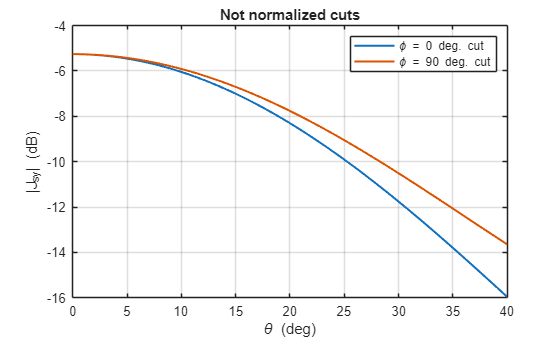

%%  Truncated lens 
D = 9 * lambda_0; % lens diameter
theta_0_truncated = deg2rad(40); % angular domain of the truncated lens
e = 1 / sqrt(er);

rho = linspace(eps, D/2, 181);
phi_lens = linspace(eps, 2*pi, 181);
[RHO, PHI_lens] = meshgrid(rho, phi_lens);

r_min_truncated = (D / 2) / sin(theta_0_truncated);
a_truncated = r_min_truncated * (1 - e * cos(theta_0_truncated)) / (1 - e^2);
c_truncated = a_truncated * e;
b_truncated = sqrt(a_truncated^2 - c_truncated^2);

Z_truncated = a_truncated * sqrt(1 - (RHO.^2 ./ b_truncated^2)) + c_truncated;
TH_truncated = atan(RHO ./ Z_truncated);
r_truncated = a_truncated * (1 - e^2) ./ (1 - e * cos(TH_truncated));

[Jsx_truncated, Jsy_truncated] = LensAperture(TH_truncated, PHI_lens, r_truncated, er, u0, v0, D, theta_0_truncated);

U_truncated = sin(TH_truncated) .* cos(PHI_lens);
V_truncated = sin(TH_truncated) .* sin(PHI_lens);

Jsx_truncated_dB = 20 * log10(abs(Jsx_truncated));
Jsy_truncated_dB = 20 * log10(abs(Jsy_truncated));

[~, idx_phi_0_lens] = min(abs(rad2deg(phi_lens) - 0));
[~, idx_phi_90_lens] = min(abs(rad2deg(phi_lens) - 90));

Jsy_cut_phi_0 = Jsy_truncated_dB(idx_phi_0_lens, :);
Jsy_cut_phi_90 = Jsy_truncated_dB(idx_phi_90_lens, :);

figure;
plot(rad2deg(TH_truncated(idx_phi_0_lens, :)), Jsy_cut_phi_0, 'LineWidth', 1.5);
hold on; grid on;
plot(rad2deg(TH_truncated(idx_phi_90_lens, :)), Jsy_cut_phi_90, 'LineWidth', 1.5);
xlabel('\theta (deg)');
ylabel('|J_{sy}| (dB)');
title('Not normalized cuts');
legend('\phi = 0 deg. cut', '\phi = 90 deg. cut', 'Location', 'northeast');

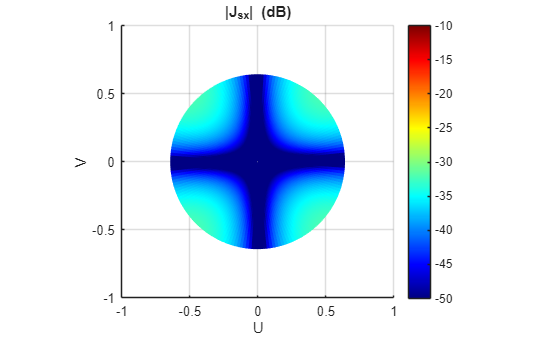


figure;
surf(U_truncated, V_truncated, Jsx_truncated_dB, 'LineStyle', 'none');
view(2); axis equal;
xlabel('U');
ylabel('V');
title('|J_{sx}| (dB)');
xlim([-1 1]);
ylim([-1 1]);
clim([-50 -10]);
colormap(jet);
colorbar;

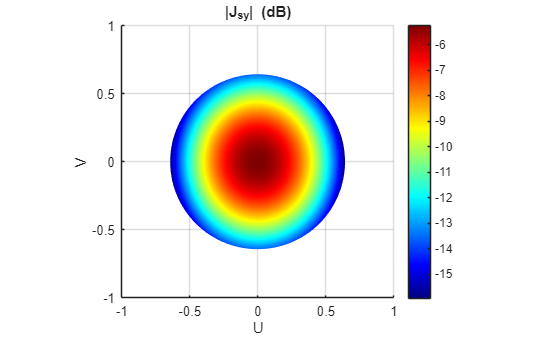


figure;
surf(U_truncated, V_truncated, Jsy_truncated_dB, 'LineStyle', 'none');
view(2); axis equal;
xlabel('U');
ylabel('V');
title('|J_{sy}| (dB)');
xlim([-1 1]);
ylim([-1 1]);
% clim([-10 0]);
colormap(jet);
colorbar;

From the figures above, it can be observed that $|J_{\mathrm{sy}} |$ has a larger amplitude than $|J_{\mathrm{sx}} |$. Notice that the field distribution is similar to the current feed given in quesiton 1. And because the the transmission coefficients for TE and TM polarizations are different, the shape of the $|J_{\mathrm{sy}} |$ is not perfectly symmetrical but a bit stretched.

## 5.  Plot the far field patterns radiated by the lens antenna of Question 4

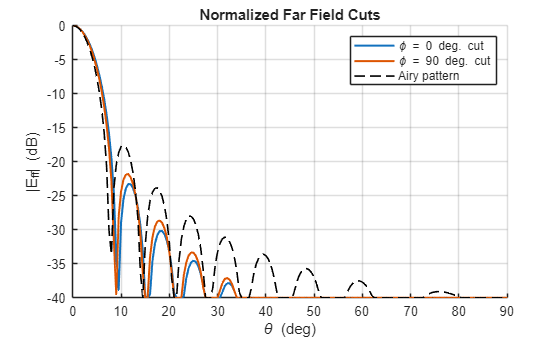

%% Far field of the truncated lens antenna
k0 = 2 * pi / lambda_0;

theta_ff = linspace(eps, pi/2 - eps, 181);
phi_ff = linspace(eps, 2*pi, 181);
phi_ff(end) = [];

[TH_ff, PH_ff] = meshgrid(theta_ff, phi_ff);
R_ff = 1;
dth_ff = theta_ff(2) - theta_ff(1);
dph_ff = phi_ff(2) - phi_ff(1);

K_xf = k0 * sin(TH_ff) .* cos(PH_ff);
K_yf = k0 * sin(TH_ff) .* sin(PH_ff);
K_zf = k0 * cos(TH_ff);

J_sx_ff = zeros(size(TH_ff));
J_sy_ff = zeros(size(TH_ff));

for m = 1:size(TH_ff, 1)
    for n = 1:size(TH_ff, 2)
        phase = exp(1j * (K_xf(m, n) * RHO .* cos(PHI_lens) + ...
            K_yf(m, n) * RHO .* sin(PHI_lens)));

        J_sx_ff(m, n) = trapz(phi_lens, trapz(rho, Jsx_truncated .* phase .* RHO, 2));
        J_sy_ff(m, n) = trapz(phi_lens, trapz(rho, Jsy_truncated .* phase .* RHO, 2));
    end
end

G_ff = EJ_SGF(1, k0, K_xf, K_yf);
[Eth_ff_x, Eph_ff_x] = farfield(k0, R_ff, TH_ff, PH_ff, K_zf, ...
    G_ff(:,:,1,1), G_ff(:,:,2,1), G_ff(:,:,3,1), J_sx_ff);
[Eth_ff_y, Eph_ff_y] = farfield(k0, R_ff, TH_ff, PH_ff, K_zf, ...
    G_ff(:,:,1,2), G_ff(:,:,2,2), G_ff(:,:,3,2), J_sy_ff);

Eth_ff = Eth_ff_x + Eth_ff_y;
Eph_ff = Eph_ff_x + Eph_ff_y;

Eabs_ff = sqrt(abs(Eth_ff).^2 + abs(Eph_ff).^2);
Eabs_ff_dB_norm = 20 * log10(Eabs_ff / (max(Eabs_ff(:)) + eps));
Eabs_ff_dB_norm = max(Eabs_ff_dB_norm, -40);

phi_ff_deg = rad2deg(phi_ff);
[~, idx_phi_0_lens] = min(abs(phi_ff_deg - 0));
[~, idx_phi_90_lens] = min(abs(phi_ff_deg - 90));

Eabs_ff_dB_norm_cut_phi_0 = Eabs_ff_dB_norm(idx_phi_0_lens, :);
Eabs_ff_dB_norm_cut_phi_90 = Eabs_ff_dB_norm(idx_phi_90_lens, :);

a_airy = D / 2;
x_airy = k0 * a_airy * sin(theta_ff);
airy = 2 * pi * a_airy^2 .* besselj(1, x_airy) ./ x_airy;
airy(x_airy == 0) = pi * a_airy^2;
airy_dB_norm = 20 * log10(abs(airy) / max(abs(airy)));
airy_dB_norm = max(airy_dB_norm, -40);

figure;
hold on; grid on;
plot(rad2deg(theta_ff), Eabs_ff_dB_norm_cut_phi_0, 'LineWidth', 1.5);
plot(rad2deg(theta_ff), Eabs_ff_dB_norm_cut_phi_90, 'LineWidth', 1.5);
plot(rad2deg(theta_ff), airy_dB_norm, 'k--', 'LineWidth', 1.2);

xlabel('\theta (deg)');
ylabel('|E_{ff}| (dB)');
title('Normalized Far Field Cuts');
legend('\phi = 0 deg. cut', '\phi = 90 deg. cut', 'Airy pattern', 'Location', 'northeast');
xlim([0 90]);
ylim([-40 0]);

We can observe a asymetric between $\phi =0\;\deg$ cut and $\phi =90\;\deg$ cut. Addtitionally, the main beam of $\phi =0\;\deg$ cut and $\phi =90\;\deg$ cut are wider than the airy pattern. We believe that the asymmetry between TM and TE transmission coefficient is the main reason of this asymmetry pattern: asymmetry between TM and TE transmission coefficient leads to a asymmetric transmitted power ratio and hence asymmetric current distribution; and this asymmetric current distribution caused the asymmetric field pattern in the end. 

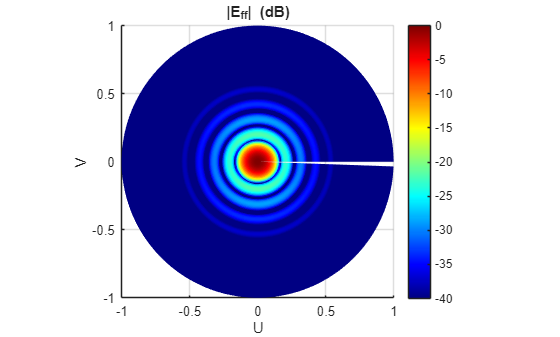

U_ff = sin(TH_ff) .* cos(PH_ff);
V_ff = sin(TH_ff) .* sin(PH_ff);

figure;
surf(U_ff, V_ff, Eabs_ff_dB_norm, 'LineStyle', 'none');
view(2); axis equal;
xlabel('U');
ylabel('V');
title('|E_{ff}| (dB)');
xlim([-1 1]);
ylim([-1 1]);
clim([-40 0]);
colormap(jet);
colorbar;

## 6.Give an estimation of the directivity and gain of the lens antenna of Question 4

The estimation of the directivity and gain of the lens antenna can be found below

%% Directivity, gain and radiation efficiency
[D_lens, P_rad_lens] = Directivity(Eabs_ff, TH_ff, dth_ff, dph_ff, 1, R_ff);
eta_rad_lens = P_rad_lens / Prad_feed;
G_lens = D_lens * eta_rad_lens;

D_max = max(D_lens(:));
G_max = max(G_lens(:));

fprintf('Lens radiated power: %.6g W\n', P_rad_lens);

Lens radiated power: 0.00093164 W


fprintf('Radiation efficiency: %.2f%%\n', 100 * eta_rad_lens);

Radiation efficiency: 82.24%


fprintf('Maximum directivity: %.2f dBi\n', 10 * log10(D_max));

Maximum directivity: 28.70 dBi


fprintf('Maximum gain: %.2f dBi\n', 10 * log10(G_max));

Maximum gain: 27.85 dBi
